# **TU: Windowing, STFT for Frequecy Features **

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

Frequency Preprocessing and Features of 

- Windowing

- STFT

> Need to use  getFFT.m   

## Include path

addpath('../../../Library')  

# Windowing

We will learn how to apply hanning window

## Dataset

### Generate Signals

A signal with a sampling frequency of 1 kHz and a signal duration of 1 second.

Form a signal containing a 50 Hz sinusoid and 120Hz sinusoid 

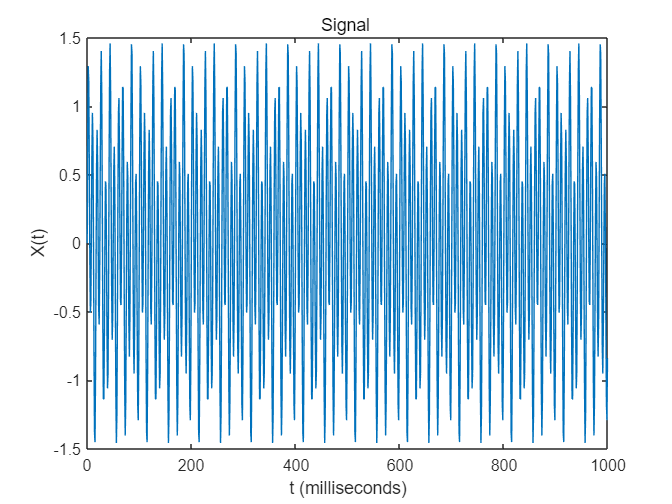

close all
clear 

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
N = 1000;             % Length of signal
t = (0:N-1)*T;        % Time vector


% Information Signal 
fa=50;      % 10Hz signal
fa2=120;    % 55Hz signal
X = 0.0 + 0.5* sin(2.0*pi*fa*t)+1*sin(2.0*pi*fa2*t); 

% Plot signals
figure()
plot(1000*t,X)
title('Signal ')
xlabel('t (milliseconds)')
ylabel('X(t)')

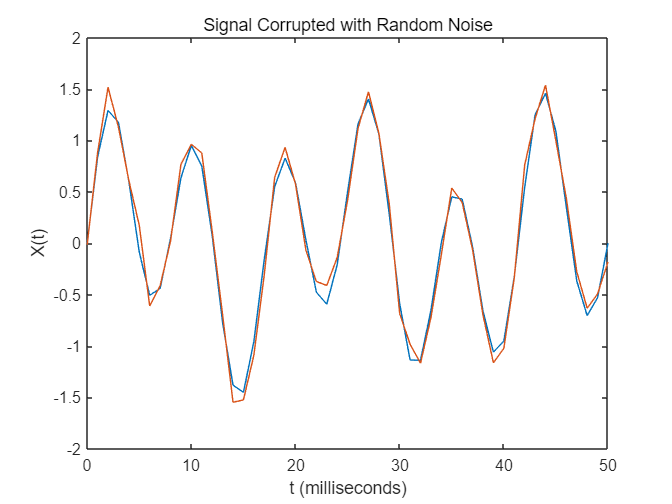



% Noise
noise=0.1*randn(size(t));

% Mixed Signal
Xm = X+noise; 


% Plot signals
figure(1)
plot(1000*t,X, 1000*t,Xm)
title('Signal Corrupted with Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')
xlim([0 50])

## Exercise : Apply Hanning Window

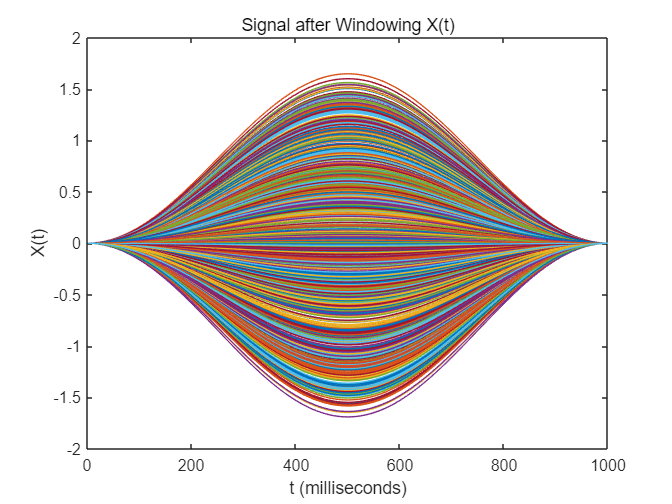

L=N;
win=hanning(L);

%%% Apply window to X by multiplication
Xw=  win .* Xm ;

%%% single-sided spectrum P1
P1=getFFT(Xw,L);
f = 0:Fs/L:Fs/2;


% Plot single-sided P1
figure
plot(Xw)
title('Signal after Windowing X(t)')
xlabel('t (milliseconds)')
ylabel('X(t)')

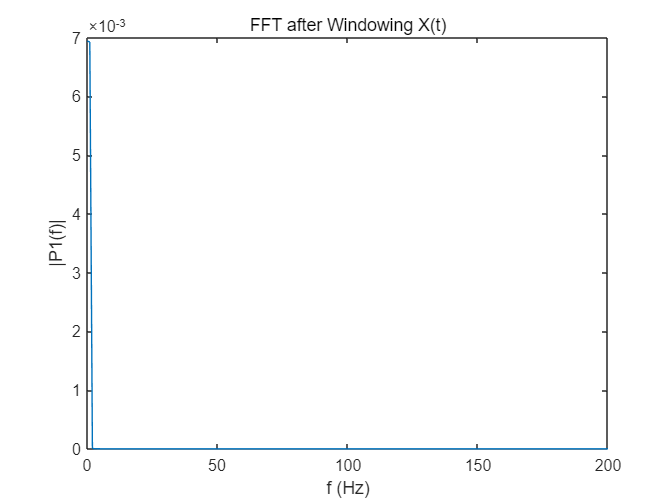

% Plot single-sided P1
figure
plot(f,P1) 
title('FFT after Windowing X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')
xlim([0 200])

# **STFT**

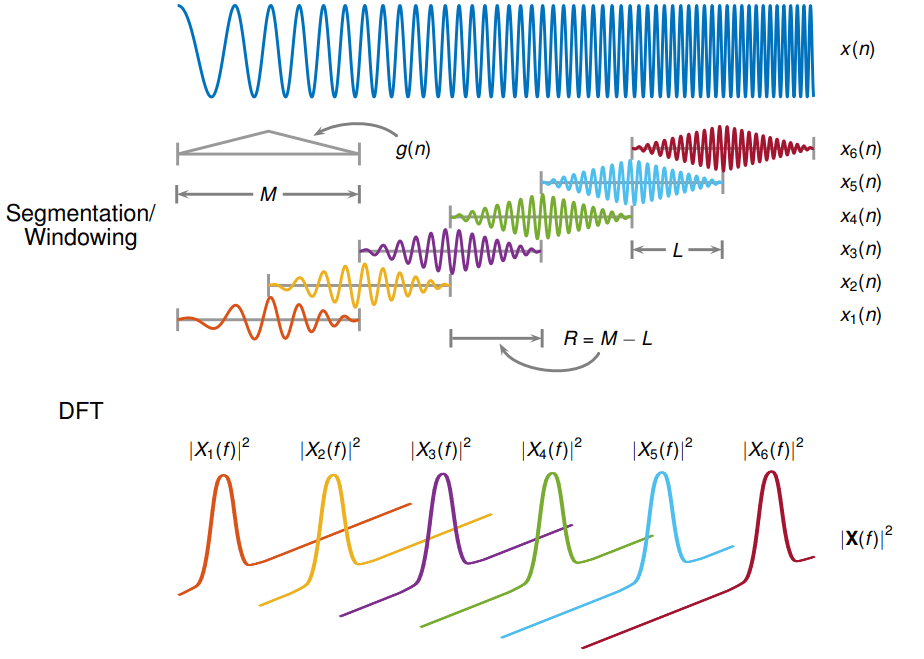

## Dataset

### Generate Signals

A chirp signal from 100 to 200 Hz in 2 secods

ts = 0:1/1e3:2;
f0 = 100;
f1 = 200;

%x = chirp(ts,f0,1,f1,'quadratic',[],'concave');
x = chirp(ts,f0,1,f1); 

## Exercise : STFT - one-sided

Compute and display the STFT of the quadratic chirp with a duration of 1 ms.

- Fs= 1000Hz.

- Divide Segments with 128 data points

- STFT Overlap of 50 datapoints

- DFT length as 128(default) with Hamming window 

fs=1e3;

[S,F,T] = stft(x, fs);

S =   -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i   0.0000 - 0.0000i   0.0001 - 0.0000i  -0.0000 - 0.0000i   0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i   0.0002 - 0.0000i   0.0000 + 0.0000i   0.0002 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i  -0.0002 - 0.0000i   0.0000 + 0.0000i  -0.0002 - 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i  -0.0002 + 0.0000i  -0.0000 + 0.0000i  -0.0003 + 0.0000i  -0.0001 - 0.0000i   0.0002 + 0.0000i   0.0002 - 0.0000i  -0.0000 + 0.0000i   0.0003 - 0.0000i  -0.0001 + 0.0000i  -0.0003 + 0.0000i   0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0002 + 0.0000i  -0.0002 + 0.0000i   0.0005 + 0.0000i  -0.0000 + 0.0000i  -0.0005 - 0.0000i   0.0002 - 0.0000i  -0.0003 - 0.0000i   0.0000 - 0.0001i  -0.0001 + 0.0000i   0.0001 + 0.0001i   0.0003 + 0.0000i  -0.0002 + 0.0001i   0.0005 - 0.0000i
  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.00

F =  -492.1875
 -484.3750
 -476.5625
 -468.7500
 -460.9375
 -453.1250
 -445.3125
 -437.5000
 -429.6875
 -421.8750


T =     0.0640
    0.0960
    0.1280
    0.1600
    0.1920
    0.2240
    0.2560
    0.2880
    0.3200
    0.3520


Visualize the STFT of each channel as a waterfall plot. 

Control the behavior of the axes using the helper function `helperGraphicsOpt`.

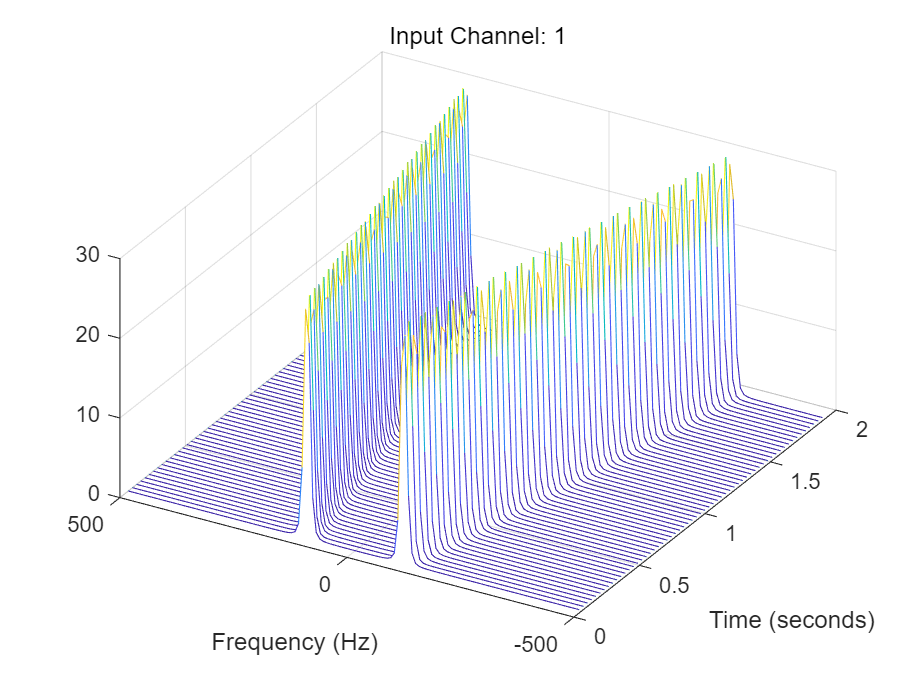

figure
waterfall(F,T,abs(S)')
helperGraphicsOpt(1)

## Exercise : STFT - Spectogram PSD

You can also use spectogram for STFT. This plots PSD of each segment.

- Fs= 1 kHz, 

- Divide segments by length of 128 samples

- Overlap of 50 samples. 

- Use 128 DFT points and the default Hamming window.

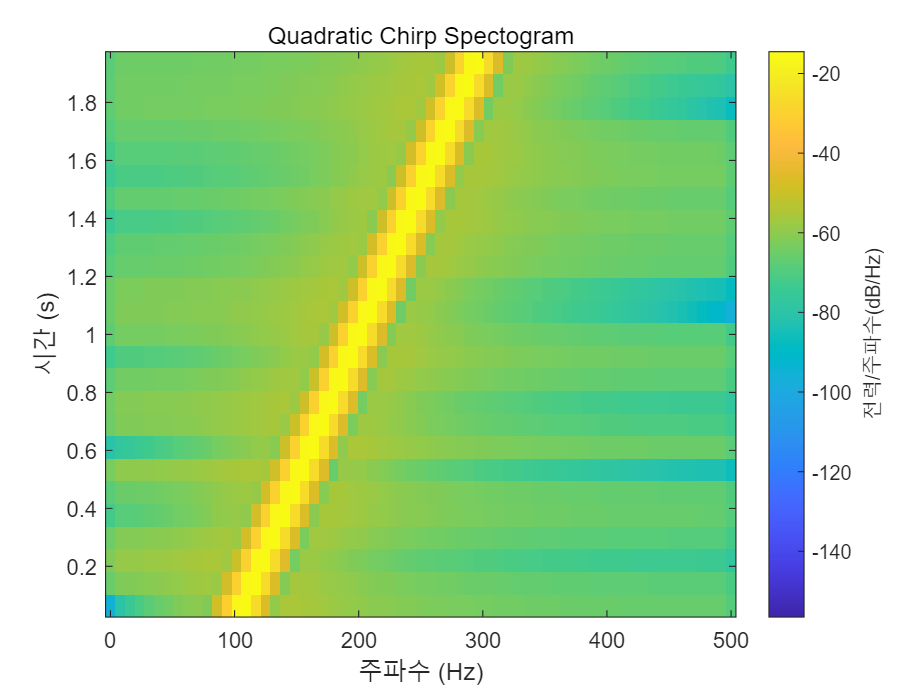

spectrogram(x,128,50,128,fs); 
title('Quadratic Chirp Spectogram')

`%helperGraphicsOpt(1)`

function helperGraphicsOpt(ChannelId)
ax = gca;
ax.XDir = 'reverse';
ax.ZLim = [0 30];
ax.Title.String = ['Input Channel: ' num2str(ChannelId)];
ax.XLabel.String = 'Frequency (Hz)';
ax.YLabel.String = 'Time (seconds)';
ax.View = [30 45];
end